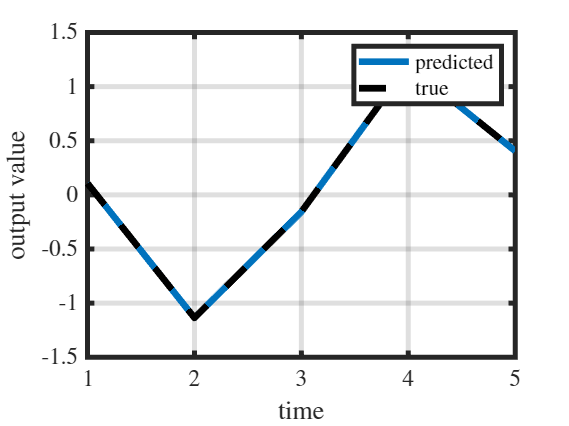

clear; close all;

% Demo dynamics
N = 5;
P = tril(toeplitz(randn(N,1)));

% Training data
J = 2;
u_cell = cell(J,1);
y_cell = cell(J,1);
for j = 1:J
    u_cell{j,1} = randn(N,1);
    y_cell{j,1} = P*u_cell{j,1};
end

% Setup GP model
gp_model = CSISOFIRGP(N);

% Train GP model
gp_model.train_gp_model(y_cell, u_cell);

% Test prediction
u  = randn(N,1);
y  = P*u;
yp = gp_model.predict(u);
figure;
plot(yp); hold on;
plot(y, '--', 'Color', 'black');
xlabel('time');
ylabel('output value');
legend('predicted', 'true');


% Test linearization
M = gp_model.linearize_at_input_trajectory(u);
disp(norm(P-M));